clear;

%Read the audio file
[audioData, fs] = audioread('Ih.wav');
display(fs);

fs = 48000

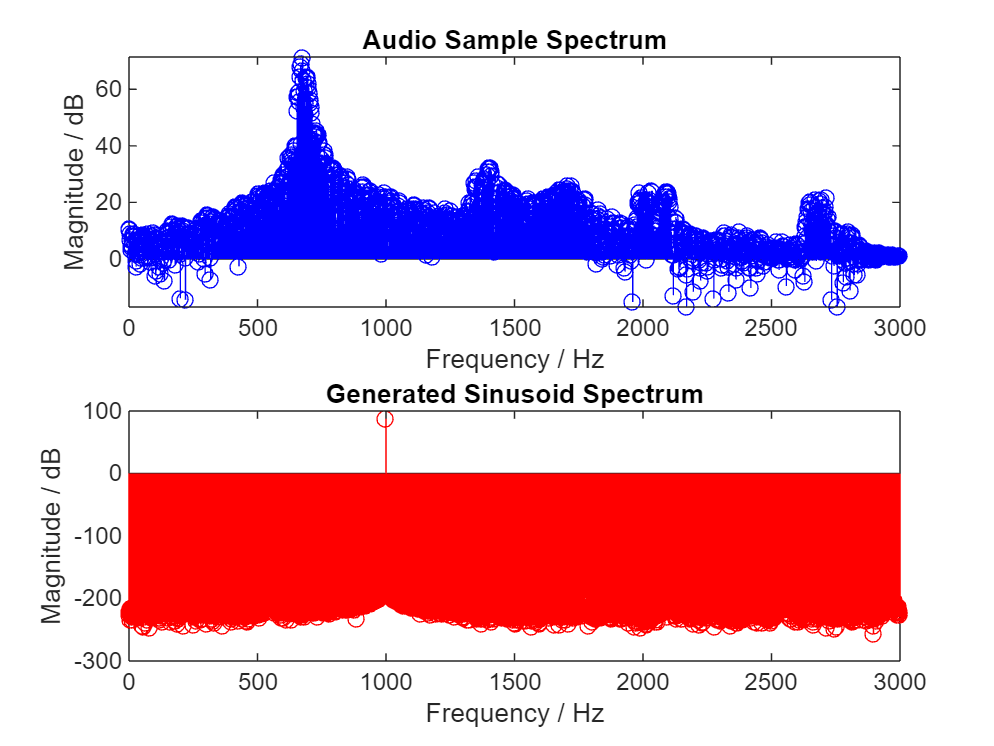


%Define the sample duration and indices
sample_duration = 1/2; % duration in seconds for 2 Hz resolution
start_sample = 1000; % starting sample index
end_sample = start_sample + sample_duration * fs - 1; % ending sample index

%Extract the audio sample
audio_sample = audioData(start_sample:end_sample);

%Compute the FFT of the audio sample
[Y_audio, freq_audio] = make_spectrum(audio_sample, fs);

%Generate a sinusoid
[x_values, y_values] = generate_sinusoid(1, 1000, 0, fs, 1);

%Compute the FFT of the sinusoid
[Y_sin, freq_sin] = make_spectrum(y_values, fs);

%Plot both spectra side by side
figure;

% Plot the audio sample spectrum
subplot(2, 1, 1);
stem(freq_audio, 20*log10(abs(Y_audio)), 'b');
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
title('Audio Sample Spectrum');
xlim([0 3000]);
%set(gca, 'YScale', 'log'); % Set the y-axis to logarithmic scale

% Plot the generated sinusoid spectrum
subplot(2, 1, 2);
stem(freq_sin, 20*log10(abs(Y_sin)), 'r');
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
title('Generated Sinusoid Spectrum');
xlim([0 3000]);



% Function to compute the spectrum
function [Y, freq] = make_spectrum(signal, fs)
    len_signal = length(signal);
    T0 = len_signal / fs;
    delta_f = 1 / T0;
    
    if mod(len_signal, 2) == 0
        f_pos = 0:delta_f:fs/2;
        f_neg = -fs/2+delta_f:delta_f:-delta_f;
    else
        f_pos = 0:delta_f:(fs/2-delta_f);
        f_neg = -(fs/2-delta_f):delta_f:-delta_f;
    end
    
    freq = [f_pos f_neg];
    Y = fft(signal);
    Y = Y(1:length(freq));
end

% Function to generate a sinusoid
function [time_vector, signal] = generate_sinusoid(a, f, phi, fs, T_s)
    time_vector = 0:1/fs:T_s-1/fs;
    signal = a*cos(2*pi*f*time_vector + phi);
end
